J=0.2

J = 0.2000

B=3

B = 3

K=250

K = 250

tau=0.001*50 % in second

tau = 0.0500

k_e=20

k_e = 2

b_e=1.2

b_e = 1.2000

m_e=0%% .1

m_e = 0

P_t=0

P_t = 0

I_t=1

I_t = 1

I_m=1.2

I_m = 1.2000

P_m=20

P_m = 20

eval(routh)

ans = 	1.0e+03 *

    0.0002    0.2512    0.3000
    0.0230    5.0000         0
    0.2077    0.3000         0
    4.9668         0         0
    0.3000         0         0


eval(aa1)

ans =     -2723200
     1189500




clear s; syms s
phy=tf([K],[1, 0]);

env=tf([k_e],[1 0]);
env2=tf([1/I_t b_e k_e],[1 0])


env2 =
 
  s^2 + 1.2 s + 2
  ---------------
         s
 
Continuous-time transfer function.



syms s;
x=s

$$x = s$$

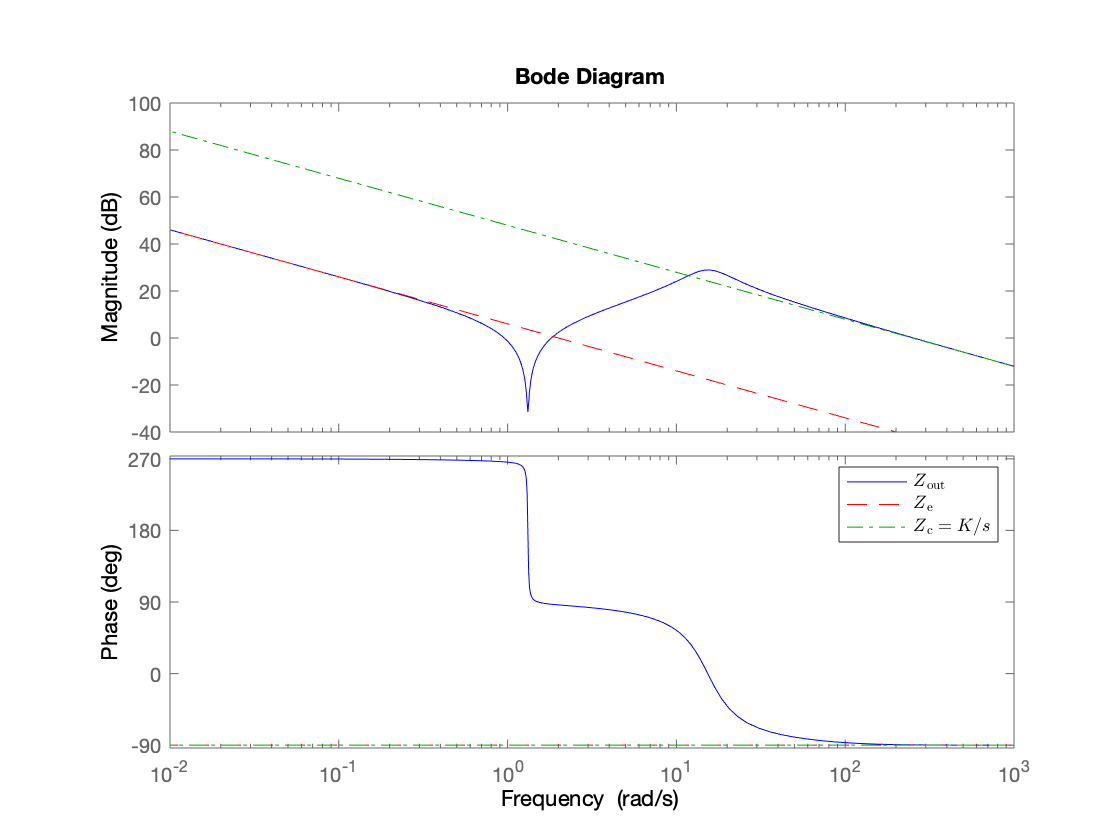

[numa dena]=numden(eval(Z2));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
sys=tf([numa],[dena 0]);

% Normal below
bode(sys,'b-',env,'r--',phy,'g-.') 
h = legend('$Z\_{\mathrm{out}}$', '$Z\_{\mathrm{e}}$', '$Z\_{\mathrm{c}}=K/s$'); set(h, 'Interpreter', 'latex');


% tau below
% tau=0.01;
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys2=tf(numa,[dena 0]);
% tau=0.1
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys3=tf(numa,[dena 0]);
% figure
% bode(sys,'b-',sys2,'r--',sys3,'g-.')
% h = legend({'$\tau=0.01$', '$\tau=0.1$','$\tau=1$'},'Location','northwest'); set(h, 'Interpreter', 'latex');

%Pt below
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys=tf(numa,[dena 0]);
% P_t=0.01;
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys2=tf(numa,[dena 0]);
% P_t=0.1
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys3=tf(numa,[dena 0]);
% figure
% bode(sys,'b-',sys2,'r--',sys3,'g-.')
% h = legend({'$P\_{\mathrm{t}}=0.001$', '$P\_{\mathrm{t}}=0.01$','$P\_{\mathrm{t}}=0.1$'},'Location','northwest'); set(h, 'Interpreter', 'latex');
% title('')
% I_m is below
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys=tf(numa,[dena 0]);
% I_m=200;
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys2=tf(numa,[dena 0]);
% I_m=300;
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys3=tf(numa,[dena 0]);
% figure
% bode(sys,'b-',sys2,'r--',sys3,'g-.')
% h = legend({'$I\_{\mathrm{m}}=100$', '$I\_{\mathrm{m}}=200$','$I\_{\mathrm{m}}=300$'},'Location','northwest'); set(h, 'Interpreter', 'latex');
% 
% title('')